horizon = 5000; % time horizon of the simuation
% Set up the figure ahorizon = 500; % time horizon of the simuation
dt = 0.01; % delta time
t = 0;

% Set up the figure and axis
% figure('Position', [100 100 800 600]);
limit = 20;
% axis([0 limit 0 limit]);
% axis square;
hold on;

% Set up the region
% x = linspace(0, limit, 100);
% y = linspace(0, limit, 100);

% Initialize the boids
num_boids = 20;
phase = 1;
transition_idx = 0;
% q = q;
% p = p;
[q, p] = generate_boids(num_boids, limit, 2);
% p = ones(num_boids, 2);

% q = [0, -0.3; 0, 0.3];
% p = [1, 0; 1, 0];

% the accelerations of the individual agents
accelerations = zeros(num_boids, 1);

% the bank angles of the individual agents
bank_angles = zeros(num_boids, 1);

% actuation is modelled using a first-order approxomation
% time delays in [desired] actuation: acceleration, bank angle
tau_a = 0.1;
tau_phi = 0.1;

% q = [0.3,0;1,0];
% p = [1.6,0;1.4,0];
max_vel = 1;
min_vel = 1;
max_accel = 10;
num_collisions = 0;
collisions = zeros(horizon, 1);

forces = zeros(horizon, 2);

max_distances = zeros(horizon, 1); % maximum distance between two neighbours
average_distances = zeros(horizon, 1); % average --
min_distances = zeros(horizon, 1); % minimum --
total_energies_p = zeros(horizon, 1);
total_energies_v = zeros(horizon, 1);

H_p = zeros(horizon, 1); % energy function - ||p|| squared
H_v = zeros(horizon, 1); % energy function - ||v|| squared

positions = zeros(horizon, 2);
velocities = zeros(horizon, 2);
gammas = zeros(horizon, 1);
angle_deviations = zeros(horizon, 1);

% System Params
epsilon = 1;
d = 0.07*10;
kappa = 9.8/7;
r = kappa*d;
h = 0.2;
phi_max = 45;
g = 9.8;

omega_max = max_vel / (g * tand(phi_max));

% weights for the forces
gradient_coeff = 1;
consensus_coeff = 0.0;
turning_coeff = 1e6;

% A lower bound on inter-agent distance, beyond which we consider a collision
d_th = 0.1;

sys_params = [epsilon, d, kappa, h, max_accel, ...
    phi_max, g, gradient_coeff, consensus_coeff, turning_coeff, t, phase, transition_idx];
debug = false;
% Update Loop
for i = 1:horizon
    t = t+dt;
    neighbours = findNeighbours(q, q, r);
    sys_params(11) = t;
    q;
    p;
    if debug
        p
    end

    target_accelerations = zeros(num_boids, 1);
    target_omegas = zeros(num_boids, 1);
    target_bank_angles = zeros(num_boids, 1); % just a declaration
    test_omegas = zeros(num_boids, 1);

    f = zeros(num_boids, 2);

    for j = 1:num_boids
        
        neighbours_of_j = neighbours{j};
        % Find the force acting on the jth boid
        j;
        force_on_j = generate_force(q, p, j, sys_params, false); % -- returns [acc, omega]
        
        % get the acceleration on the jth agent
        target_accelerations(j) = force_on_j(1);

        % target omegas --
        target_omegas(j) = force_on_j(2);
        test_omegas(j) = force_on_j(2);

    end

    % get the adjacency mmatrix (measures connectivity of the formation)
    a = get_unweighted_adjacency_matrix(q, r);
    g = get_weighted_adjacency_matrix(q, r);
    
    % disp(g);

    G = graph(g);
    l = laplacian(G);
    L = graph(l);
    
    comp_numbers = conncomp(L); % gives which connected component each agent belongs to
    % unique(comp_numbers)

    % form the groups
    % Get the unique IDs
    unique_ids = unique(comp_numbers);
    
    % Initialize the cell array
    cell_array = cell(1, numel(unique_ids));
    
    % Iterate through each unique ID
    for k = 1:numel(unique_ids)
        % Find indices where ID equals the unique ID
        indices = find(comp_numbers == unique_ids(k));
        % Store the indices in the cell array
        cell_array{k} = indices;
    end

    % cell_array

    q_groups = zeros(size(cell_array, 2), 2);
    p_groups = zeros(size(cell_array, 2), 2);
    for j = 1:size(cell_array, 2)
        q_groups(j, :) = mean(q(cell_array{j}, :), 1);
        p_groups(j, :) = mean(p(cell_array{j}, :), 1);
    end

    f_k = zeros(size(cell_array, 2), 2);
    
    % size(cell_array)
    

    for k = 1:size(cell_array, 2)
        k;
        force_on_k = generate_force(q_groups, p_groups, k, sys_params, true);
        f_k(k,:) = force_on_k;
    end

    for k = 1:num_boids
        target_accelerations(k) = 0.8 * target_accelerations(k) + 0.2 * f_k(comp_numbers(k), 1);
        target_omegas(k) = 0.8 * target_omegas(k) + 0.2 * f_k(comp_numbers(k), 2);
    end
    % f_k + f;
    comp_numbers;
    f_k;
    clip(target_accelerations, 0, max_accel);
    clip(target_omegas, -omega_max, omega_max);

    if phase == 3 && mod(i, 100) == 0
        % i
        % q_groups
        % p_groups
        % f_k
    end

    % % get target_bank_angles from target_omegas
    % target_bank_angles = getBankAngles(target_omegas, p);

    % % find the rate of change of acceleration and bank angles
    % accelerations_dot = (target_accelerations - accelerations) / tau_a;
    % bank_angles_dot = (target_bank_angles - bank_angles) / tau_phi;
    % 
    % % update the accelerations and bank angles
    % accelerations = accelerations + dt * accelerations_dot;
    % bank_angles = bank_angles + dt * bank_angles_dot;
    % 
    % % convert bank angles to omegas
    % omegas = getOmegas(bank_angles, p);

    for j = 1:num_boids

        j;
        if debug
            target_accelerations
            target_omegas
            p;
        end
        force_on_j = [target_accelerations(j), target_omegas(j)];

        %-------------------------- actuator saturation -----------------
        % if vecnorm(force_on_j, 2, 2) > max_accel
        %     force_on_j = (max_accel/vecnorm(force_on_j, 2, 2)) * force_on_j;
        % end

        % ------------------------- velocity control --------------------
        % update velocity
        p(j,:) = force_on_j(1) * (p(j,:) / vecnorm(p(j,:),2,2)) * dt + p(j,:);
        dtheta = force_on_j(2) * dt;
        p(j,:) = ([cos(dtheta), sin(dtheta); -sin(dtheta), cos(dtheta)] * p(j,:)')';
        speed = vecnorm(p(j,:), 2, 2);
        
        % clip the velocity
        p(j, :) = p(j, :) / speed * clip(speed, min_vel, max_vel);

        % update position
        q(j,:) = q(j,:) + p(j,:)*dt;
    end

    d_alpha = sigmanorm(d, epsilon);
    r_alpha = sigmanorm(d, epsilon);
    for j = 1:num_boids
        for k = 1:num_boids
            if j == k
                continue
            end
            total_energies_p(i) = total_energies_p(i) + 0.5*psi_alpha(vecnorm(q(j,:)-q(k,:),2,2), @phi_alpha, d_alpha, 50, 100, epsilon, h, d_alpha, r_alpha); 
            total_energies_v(i) = total_energies_v(i) + 0.5*psi_alpha(vecnorm(q(j,:)-q(k,:),2,2), @phi_alpha, d_alpha, 50, 100, epsilon, h, d_alpha, r_alpha); 
            angle_deviations(i) = angle_deviations(i) + 1/2 * (angle(p(j,:), p(k,:))/(2*pi))^2;
        end
    end

    total_energies_p(i) = total_energies_p(i) + sum(vecnorm(p,2,2).^2, 1);
    total_energies_v(i) = total_energies_v(i) + sum(vecnorm(p - mean(p,1),2,2).^2, 1);
 
    if phase == 1 && angle_deviations(i) < 0.01
        phase_change_index1 = i;
        phase = 2
        max_vel = 5;
        transition_idx = 0;
        sys_params(12) = phase;
    end

    if phase == 2 && transition_idx <= 1
        transition_idx = transition_idx + 0.01;
        sys_params(13) = transition_idx;
    end

    if transition_idx >= 1 && phase == 2
        phase_change_index2 = i;
        phase = 3
        sys_params(12) = phase;
    end

    % check for collisions
    collisions(i) = check_collisions(q, d_th);
    num_collisions = num_collisions + collisions(i);

    % get inter-agent distances
    max_distance = max(g, [], 'all'); % max distance between any two neighbours
    min_distance = min(g(g > 0), [], 'all'); % min distance between any two neighbours
    average_distance = mean(g(g > 0), "all"); % average distance all neighbours
    max_distances(i) = max_distance;
    if isempty(min_distance)
        min_distance = 0;
    else
        min_distances(i) = min_distance;
    end
    average_distances(i) = average_distance;

    % get velocities and positions of agents for plotting
    % positions(i, :) = q(:, 2)';
    % velocities(i, :) = p(:, 2)';
    % gammas(i) = p(1, 1);

    H_p(i) = 1/2 * sum(vecnorm(p, 2, 2));
    H_v(i) = 1/2 * sum(vecnorm(p - mean(p,1), 2, 2));

    s = sparse(g);
    xm = mean(q(:,1));
    ym = mean(q(:,2));
    window = 15;
    xlim([xm-window, xm+window]);
    ylim([ym-window, ym+window]);
    xl = xlim;
    yl = ylim;
    dx = xl(2) - xl(1);
    dy = yl(2) - yl(1);
    scalex = dx/25;
    scaley = dy/25;

    % plots the velocity vectors and positions
    cla;
    gplot(s,q); 
    quiver([q(:,1)], [q(:,2)], scalex*(p(:,1)./vecnorm(p,2,2)), scaley*(p(:,2)./vecnorm(p,2,2)), 0, 'Color', 'k');
    plot(q(:,1), q(:,2), 'ro', 'MarkerSize', 3.5, 'MarkerFaceColor','red');

    % save the plots at given time intervals
    if i == 1
        plot_name = "plots/turning_start.png";
        exportgraphics(gca, plot_name);
    end

    if phase == 2 && transition_idx == 0
        plot_name = "plots/transition_start.png";
        exportgraphics(gca, plot_name);
    end

    if phase == 3
        plot_name = "plots/flocking_start.png";
        exportgraphics(gca, plot_name);
    end

    if i == horizon
        plot_name = "plots/flocking_finish.png";
        exportgraphics(gca, plot_name);
    end

    % if mod(i, 295) == 5
    %     cla;
    %     gplot(s,q); 
    %     quiver([q(:,1)], [q(:,2)], scalex*(p(:,1)./vecnorm(p,2,2)), scaley*(p(:,2)./vecnorm(p,2,2)), 0, 'Color', 'k'); 
    %     plot(q(:,1), q(:,2), 'ro', 'MarkerSize', 3.5, 'MarkerFaceColor','red');
    %     title("t = " + num2str(i/100));
    %     plot_name = "turning_"+num2str(i/100)+".png";
    %     exportgraphics(gca, plot_name);
    % end 

    % prints the ids of the boids
    % for k = 1:num_boids
    %     text(p(k,1), p(k,2), string(k));
    % end

    % prints the deviation energy, defined in olfati-saber for alpha lattices
    % if mod(i, 1000) == 0
    %     devE = (0.5*sum(psi(g-d))) / (1 + 0.5*sum(a));
    % end

    pause(0.01);
    % if mod(i, 100) == 1
    %     dir = sum(p ./ vecnorm(p,2,2));
    %     dir/vecnorm(dir,2,2)
    % end
end

phase = 2

phase = 3

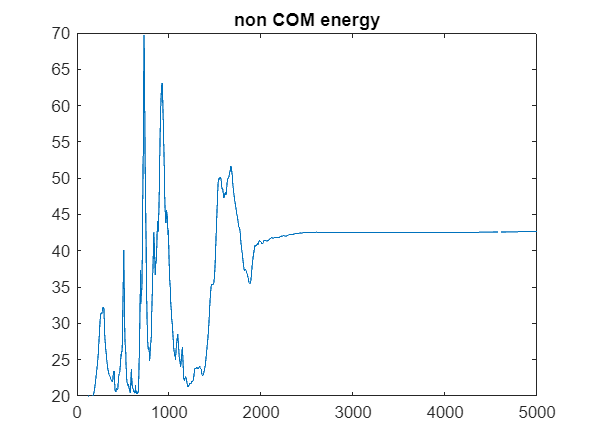

hold off;

vecnorm(p(vecnorm(p, 2, 2) < 1), 2, 2)


ans =

  0×1 empty double column vector



vecnorm(p, 2, 2)

ans =     1.0004
    1.0007
    1.0003
    1.0006
    1.0003
    1.0001
    1.0000
    1.0001
    1.0001
    1.0006


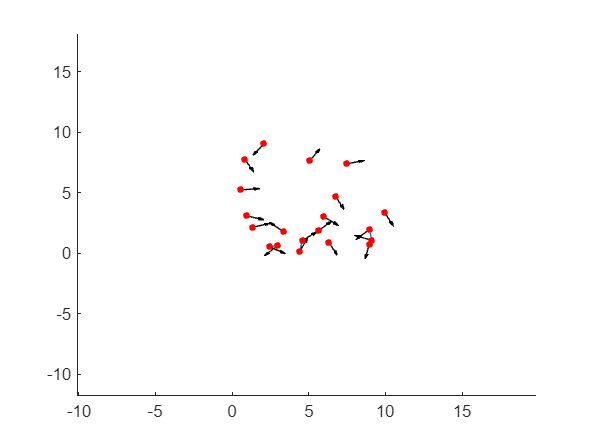

% 
% plot(collisions);
% title("Collisions");
% plot_name = "Collisions.png";
% % exportgraphics(gca, plot_name);
% % 
a1 = plot(max_distances, 'b-');
hold on;
plot(min_distances, 'b-');
% Fill the area between the lines
x_values = 1:numel(max_distances);
fill([x_values fliplr(x_values)], [max_distances' fliplr(min_distances')], 'c', 'EdgeColor', 'none', 'FaceAlpha', 0.2);
a2 = plot(average_distances, 'k-');
a3 = plot([0, horizon], [d, d], 'g--');
a4 = plot([0, horizon], [d_th, d_th], 'r--');
xline([phase_change_index1, phase_change_index2], 'k-.');
hold off;
legend([a1, a2, a3, a4], {'Maximum/Minimum', 'Average',  'Desired', 'Collision Boundary'})
title("Inter-Agent Distances (Only Neighbours)");
plot_name = "plots/Interagent_distances.png";
% exportgraphics(gca, plot_name);
% 
% plot(H_v);
% title("CM Frame Velocity-Based Energy ($H = \frac{1}{2}\sum_i||p_i-\bar{p}||^2$)", Interpreter="latex");
% plot_name = "H_v.png";
% exportgraphics(gca, plot_name);
% 
% plot(H_p);
% title("Velocity-Based Energy ($H = \frac{1}{2}\sum_i||p_i||^2$)", Interpreter="latex");
% plot_name = "H_p.png";
% exportgraphics(gca, plot_name);

% x = (1:phase_change_index1)';
% f = fit(x, angle_deviations(1:phase_change_index1), 'exp1');
% plot(angle_deviations(1:phase_change_index1), '-', 'LineWidth', 1);
% hold on;
% legend('data')
% plot(f, 'r--');
% title("Angle Deviation Energy");
% plot_name = "plots/expfit.png";
% % exportgraphics(gca, plot_name);
hold off;

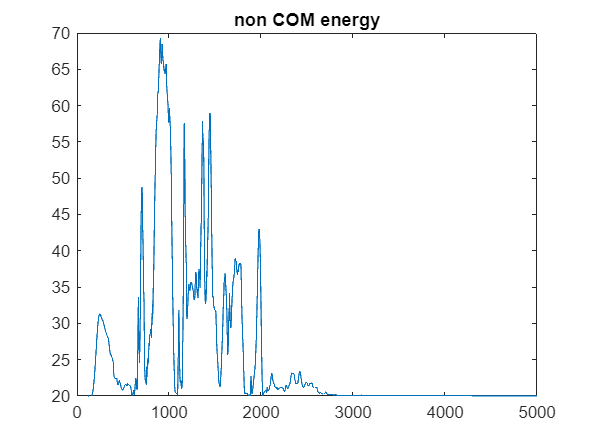


plot(total_energies_p);
hold on;
title('non COM energy');
hold off;

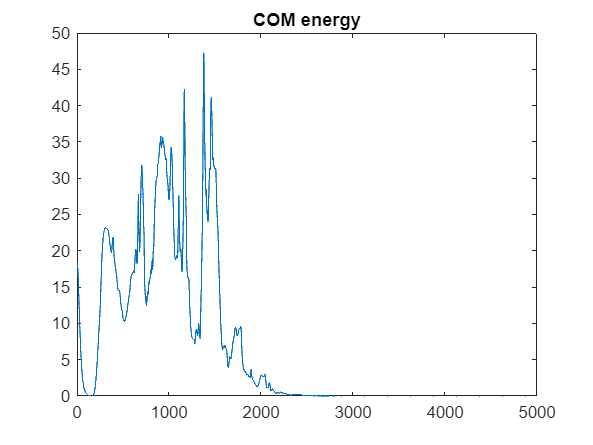


plot(total_energies_v);
hold on;
title('COM energy');
hold off;


% plot(velocities(:,2)-velocities(:,1));
% title("Velocities [along y]");
% plot(positions(:,2)-positions(:,1));
% yline(d, 'k--', 'LineWidth', 1);
% title("Distance [along y]");
% plot(gammas);
% plot(cos(gammas));
% title("Error in Heading");

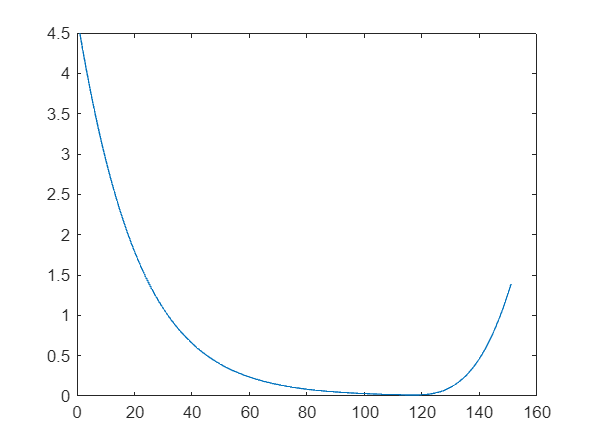

plot(total_energies_v(50:200))

% p1 = p(p(:,2) > 0,:)
% p2 = p(p(:,2) < 0,:)
% delp = p2(1,:) - p1(1,:)
% delp(1)
% l = atan2(delp(1,2)*p1(1,1)-delp(1,1)*p1(1,2), delp(1,1)*p1(1,1)+delp(1,2)*p1(1,2))
% tanh(sin(l/2))
% vecnorm(l,2,2)*tanh(sin(l/2))

function out = angle(v1, v2)
    v1;
    v2;
    cross = v1(2)*v2(1) - v1(1)*v2(2);
    dot = sum(v1 .* v2);
    out = atan2(cross, dot);
    if cross == 0 && dot < 0
        out = pi;
    end
end

function y = sigmanorm(x, eps)
    y = 1/eps .* (sqrt(1 + eps*x.^2) - 1);
end

function y = sigma(x, eps)
    y = x ./ (1  + eps*sigmanorm(x, eps));
end

function  y = bump(x, h)
    y = zeros(size(x));
    y(x >= 0 & x < h) = 1;
    y(x >= h & x < 1) = 0.5 * (1 + cos(pi * (x(x >= h & x < 1) - h) / (1 - h)));
    y(x >= 1) = 0;
end
    
function y = phi(x, a, b, eps)
    c = abs(a - b) / sqrt(4*a*b);
    y = 1/2 * ((a+b)*sigma(x+c, eps) + (a-b));
end

function y = phi_alpha(x, a, b, eps, h, d, r)
    y = bump(x/r, h).*phi(x-d, a, b, eps);
end

function y = psi_alpha(x, f, d, varargin)
    y = arrayfun(@(xi) integral(@(s) f(s, varargin{:}), d, xi), x);
end

function out = generate_force(q, p, id, sys_params, flag)

    %-----------------------------------------------------------------
    % function out = sigma(z, epsilon)
    %     out = z ./ sqrt(1 + epsilon*z);
    % end
    % 
    % function rho = bump(z, h)
    %     rho = zeros(size(z));
    %     rho(z >= 0 & z < h) = 1;
    %     rho(z >= h & z <= 1) = (1/2) * (1 + cos(pi * ((z(z >= h & z <= 1) - h)/(1 - h))));
    % end
    % 
    % function out = phi(z, a, b) 
    %     % merely scaling and shifting the sigma function
    %     c = abs(a-b)/sqrt(4*a*b);
    %     out = 0.5 * ((a+b) * sigma(z+c, 1) + (a-b));
    % end
    % 
    % function out  = phi_alpha(z, r_alpha, d_alpha, a, b)
    %     out = bump(z/r_alpha, 0.2) .* phi(z-d_alpha, a, b);
    % end
    % 
    % function out = sigmanorm(z, epsilon)
    %     out = (1/epsilon) * (sqrt(1 + epsilon * z.^2) - 1);
    % end
    %------------------------------------------------------------------

    % q(id,:) -- position of the jth boid
    % q(neighbour_ids,:) -- positions of the neighbouring boids
    % p(id,:) -- velocity of the jth boid
    % p(neighbour_ids,:) -- velocities of the neighbouring boids
    
    % ---------------------- system params ---------------------------
    epsilon = sys_params(1);
    d = sys_params(2);
    kappa = sys_params(3);
    if ~flag
        r = kappa * d;
        neighbours = findNeighbours(q(id, :), q, r);
        neighbours;
        q;
        neighbour_ids = neighbours{1};
    else
        distances = pdist2(q, q(id,:));
        distances(distances == 0) = inf;
        neighbour_ids = find(distances == min(distances));
        distances;
        neighbour_ids;
        min_x = min(distances);
        r = 2 * kappa * min_x / (kappa + 1);
        d = 2 * min_x / (kappa + 1);
        if r < kappa * sys_params(2)
            id;
            d = sys_params(2);
            r = kappa * d;
        end
        % pause(0.01)
    end
    h = sys_params(4);
    max_accel = sys_params(5);
    phi_max = sys_params(6);
    g = sys_params(7);
    C = g * tand(phi_max);
    
    gradient = sys_params(8);
    consensus = sys_params(9);
    turning = sys_params(10);
    t = sys_params(11);
    phase = sys_params(12);
    transition_idx = sys_params(13);
    
    % --------------------- transformed params -----------------------
    r_alpha = sigmanorm(r, epsilon);
    d_alpha = sigmanorm(d, epsilon);
    
    heading = atan2(p(id, 2), p(id, 1));
    
    % --------------------- gradient term ----------------------------
    q_delta = q(neighbour_ids,:) - q(id,:);
    n_ij = q_delta ./ sqrt(1 + epsilon*vecnorm(q_delta, 2, 2));
    u_grad = 5*sum(phi_alpha(sigmanorm(vecnorm(q(neighbour_ids,:) - q(id,:),2,2), epsilon), 50, 100, epsilon, h, d_alpha, r_alpha) .* n_ij, 1);
    if phase == 1
        u_grad = u_grad * 0;
    elseif phase == 2
        u_grad = u_grad * transition_idx;
    else 
        u_grad = u_grad;
    end
    % u_grad = -sum(phi_alpha(sigmanorm(q(neighbour_ids,:) - q(id,:), epsilon), r, d, 100000, 100000) .* n_ij, 1);
    
    % % --------------------- consensus term ---------------------------
    % a_ij = bump(sigmanorm((q(neighbour_ids,:) - q(id,:)/r_alpha), epsilon), h);
    % % a_ij = bump(sigmanorm((q(neighbour_ids,:) - q(id,:)/r), epsilon), h);
    % u_cons = sum(a_ij .* p(neighbour_ids,:) - p(id,:), 1);
    % 
    % %---------------------- linear acceleration term -----------------
    % lin_accel = 0;
    % sum_term1 = 0;
    % for j = 1:length(neighbour_ids)
    %     sum_term1 = sum_term1 + sum((p(j,:) - p(id,:)) .* [cos(heading), sin(heading)]);
    % end
    % lin_accel = tanh(sum_term1) * [cos(heading), sin(heading)];
    % 
    % %---------------------- turning term -----------------------------
    % u_turn = 0;
    % sum_term = 0;
    % for j = 1:length(neighbour_ids)
    %     delta_p = p(id,:) - p(j,:);
    %     eta_ij = atan2(delta_p(2) * p(id,1) - delta_p(1) * p(id,2), sum(delta_p .* p(id,:)));
    %     if eta_ij == 0 && sum(delta_p .* p(id,:)) < 0
    %         eta_ij = pi;
    %     end
    %     if isnan(eta_ij)
    %         eta_ij = 0;
    %     end
    %     sum_term = sum_term + sin(eta_ij / 2);
    % end
    % B = 1;
    % u_turn = -1 / vecnorm(p(id,:),2,2) * tanh(B*sum_term) * [-sin(heading), cos(heading)];
    % % --------------------- navigation term --------------------------
    % u_nav = [0, 0];
    % u_nav = -100*(q(id,:) - [5,5]);
    
    %-----------------------------------------------------------------
    
    % % u_grad
    % % u_cons
    % % u_turn
    id;
    % % a_xy = gradient*u_grad + consensus*u_cons + u_nav;
    % u_grad = gradient*u_grad;
    % lin_accel_grad = sum(u_grad .* [cos(heading), sin(heading)]) * [cos(heading), sin(heading)];
    % turn_grad = sum(u_grad .* [-sin(heading), cos(heading)]) * [-sin(heading), cos(heading)];
    % 
    % total_lin_accel = lin_accel + lin_accel_grad;
    % total_turn = u_turn + turn_grad;
    % 
    % if abs(total_lin_accel) > max_accel
    %     total_lin_accel = sign(sum(total_lin_accel.*[cos(heading), sin(heading)])) * max_accel/vecnorm(total_lin_accel,2,2) * [cos(heading), sin(heading)];
    % end
    % 
    % if abs(total_turn) > C/vecnorm(p(id,:),2,2)
    %     total_turn = (C/vecnorm(p(id,:),2,2)) * (total_turn/vecnorm(total_turn,2,2));
    % end
    % 
    % a_xy = total_lin_accel + total_turn;
    % perp
    
    %-------- convert to x,y to linear,omega acceleration ------------
    % below is the desired control input
    
    % cap the control inputs and introduce delays 
    % if abs(out(1)) > max_accel
    %     out(1) = out(1)/abs(out(1)) * max_accel;
    % end
    % 
    % if abs(out(2)) > g*tan(phi_max*pi/180) / vecnorm(p(id,:), 2, 2)
    %     out(2) = g*tan(phi_max*pi/180) / vecnorm(p(id,:), 2, 2);
    % end
        
    %-----------------------------------------------------------------
    
    adj = bump(sigmanorm((q - q(id,:)/r_alpha), epsilon), h);
    target_heading_vector = sum(p, 1) - p(id, :);
    target_heading_vector = target_heading_vector / vecnorm(target_heading_vector,2,2);
    target_heading_vector = [1, 0];
    speed = vecnorm(p(id,:),2,2);
    direction = p(id,:) / speed;
    if phase == 1 || phase == 2
        alpha = 8*angle(p(id,:), target_heading_vector);
    elseif phase == 3
        alpha = 3*angle(p(id,:), target_heading_vector);
    end

    u_grad_parallel = sum(u_grad .* direction) * direction;
    acceleration = vecnorm(u_grad_parallel,2,2)*sign(sum(u_grad .* direction));
    
    u_grad_perp = u_grad - u_grad_parallel;
    turning = vecnorm(u_grad_perp, 2, 2);
    s = sign(sum(u_grad_perp .* [-direction(2), direction(1)]));
    turning = -1*s*turning;
    
    omega = (alpha/pi + turning) / speed;

    % Attempt a damping term
    damping_acceleration = 0;
    for j = 1:length(neighbour_ids)
        j;
        neighbour_ids;
        p;
        q_j = q(neighbour_ids(j), :);
        p_j = p(neighbour_ids(j), :);
        speed_j = vecnorm(p_j, 2, 2);
        gamma = angle(p(id, :), p_j);
        damping_acceleration = 20*(speed_j*cos(gamma) - speed);
    end

    if phase == 1
        damping_acceleration = 0 * damping_acceleration;
    elseif phase == 2
        damping_acceleration = transition_idx * damping_acceleration;
    else
        damping_acceleration = damping_acceleration;
    end

    acceleration = acceleration + damping_acceleration;

    out = [acceleration, omega];

    if length(q) < 5
        id;
        q(id,:);
        p(id,:);
        out;
        pause(0.01);
    end

    % set NaN values to zero, else the boid disappears
    out(isnan(out)) = 0;
end

function bank_angles = getBankAngles(omegas, velocities)
    % convert omega to bank angle
    % uses a car on a banked road model

    % Value of gravity
    g = 1;

    % We need the speeds to calculate the bank angles
    speeds = vecnorm(velocities, 2, 2);

    % Formula : omega = gtan(phi) / speed
    bank_angles = atan(omegas .* speeds / g);
end

function omegas = getOmegas(bank_angles, velocities)
    % uses a car on a banked road model
    % value of gravity
    g = 1;

    % speeds
    speeds = vecnorm(velocities, 2, 2);

    % Formula : omega = gtan(phi) / speed
    omegas = g * tan(bank_angles) ./ speeds;
end

function out = psi(z)
 
    out = z.^2;

end


function neighbors = findNeighbours(boids, all_boids, range)
    
    neighbors = rangesearch(all_boids, boids, range);
    neighbors = cellfun(@(a) a(2:end), neighbors, 'UniformOutput', false);

end


function number_of_collisions = check_collisions(boids, threshold_distance)

    number_of_collisions = 0;
    distances = pdist2(boids, boids);
    crashes = zeros(size(boids,1));
    crashes(distances <= threshold_distance) = 1;
    crashes = crashes - eye(size(boids,1));
    number_of_collisions = sum(crashes, 'all');
    number_of_collisions = number_of_collisions / 2;

end


function out = get_unweighted_adjacency_matrix(points, range)

    function out = cell2logic(c, n)
    out = zeros(1, n);
    out(c) = 1;
    end

    neighbours = findNeighbours(points, points, range);
    out = cell2mat(cellfun(@(a) cell2logic(a, size(points, 1)),  neighbours, 'UniformOutput', false));

end


function out = get_weighted_adjacency_matrix(points, range)

    distances = pdist2(points, points);
    out = get_unweighted_adjacency_matrix(points, range) .* distances;

end